close all
clear
clc

# Image filtering (1)

This demo shows how image filters can be used to enhance the image information content, which means for example improving the visibility of features of interest.

Different image filters are used for:  

- Image denoising

- Improving visibility of object edges 

The application of denoising filters (e.g. median filters, Gaussian filters) may improve the SNR, but it can reduce the sharpness of relevant edges in the images. 

## 1) Filters in the spatial domain for image denoising

Load and display the image

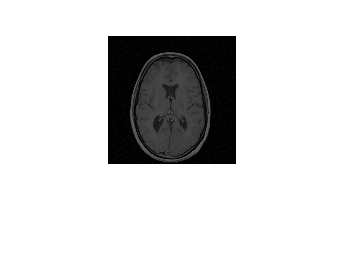

Im=imread('MRIslice_noise.png');
imshow(Im)

Visualize a central profile

size(Im)

ans =    128   128


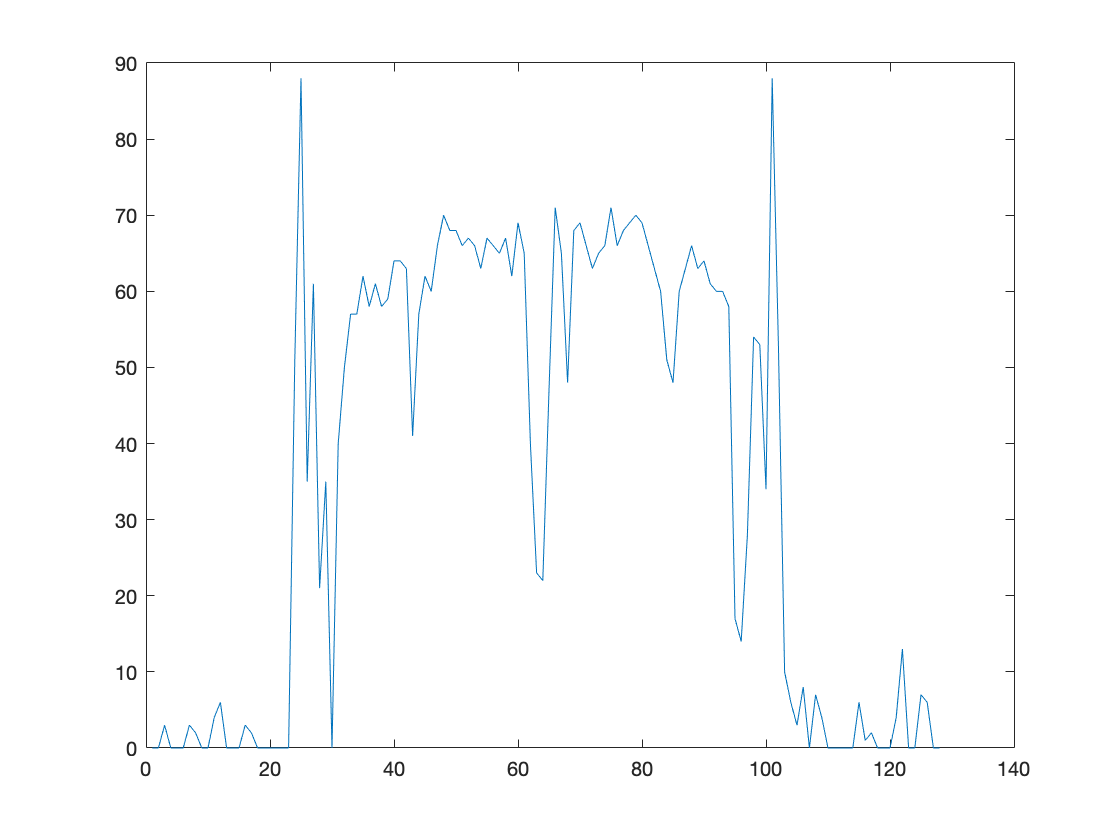

sl=round(size(Im,1)/2); % we choose a central row
figure; plot(Im(sl,:))

Specify axis labels, etc.

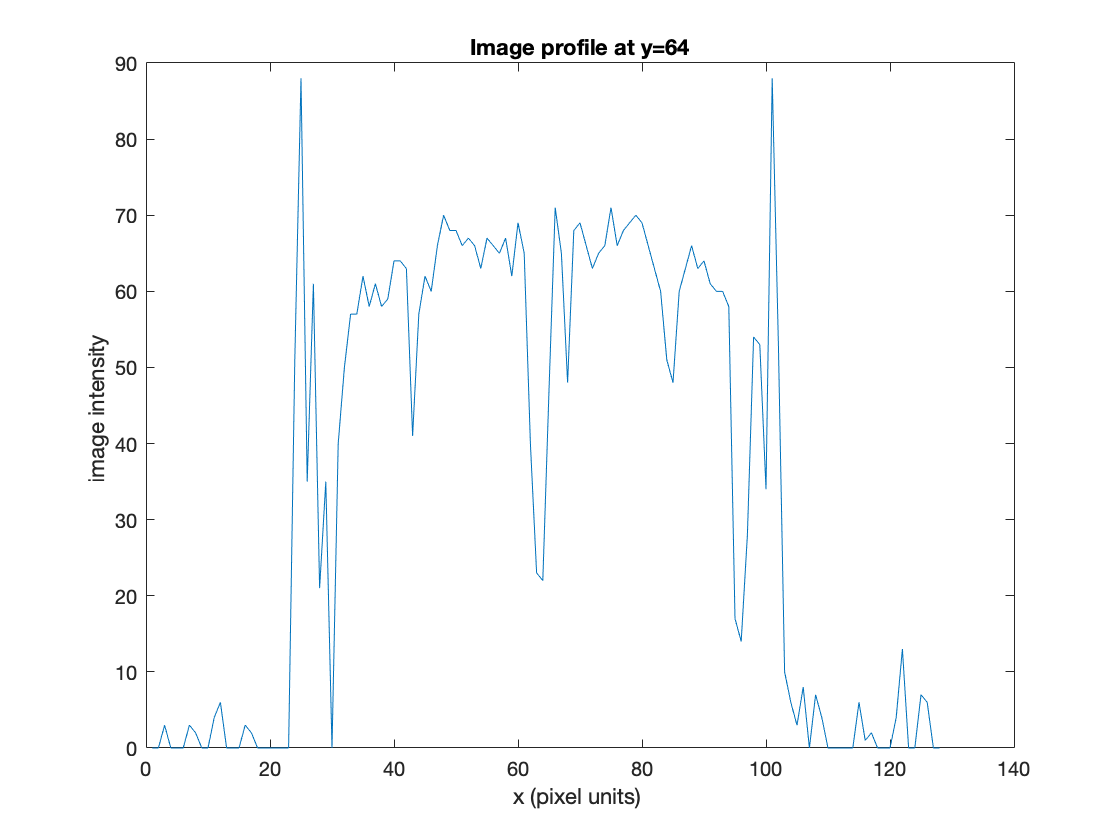

figure
plot(Im(sl,:))
xlabel('x (pixel units) ')
ylabel('image intensity ')
title(strcat('Image profile at y= ',num2str(sl)));

Implement a spatial smoothing with a 2-D Gaussian filter with `imgaussfilt`

Syntax: 

`    B =` `imgaussfilt``(A) ` % default standard deviation is 0.5

`    B =` `imgaussfilt``(A,sigma) `

`imgaussfilt `works with` unint8,` however, as we probably will continue the analysis with other operations, we will convert `uint8` to `double` right now.

Im=double(Im);
Im_G = imgaussfilt(Im); 

Compare the original and filtered images

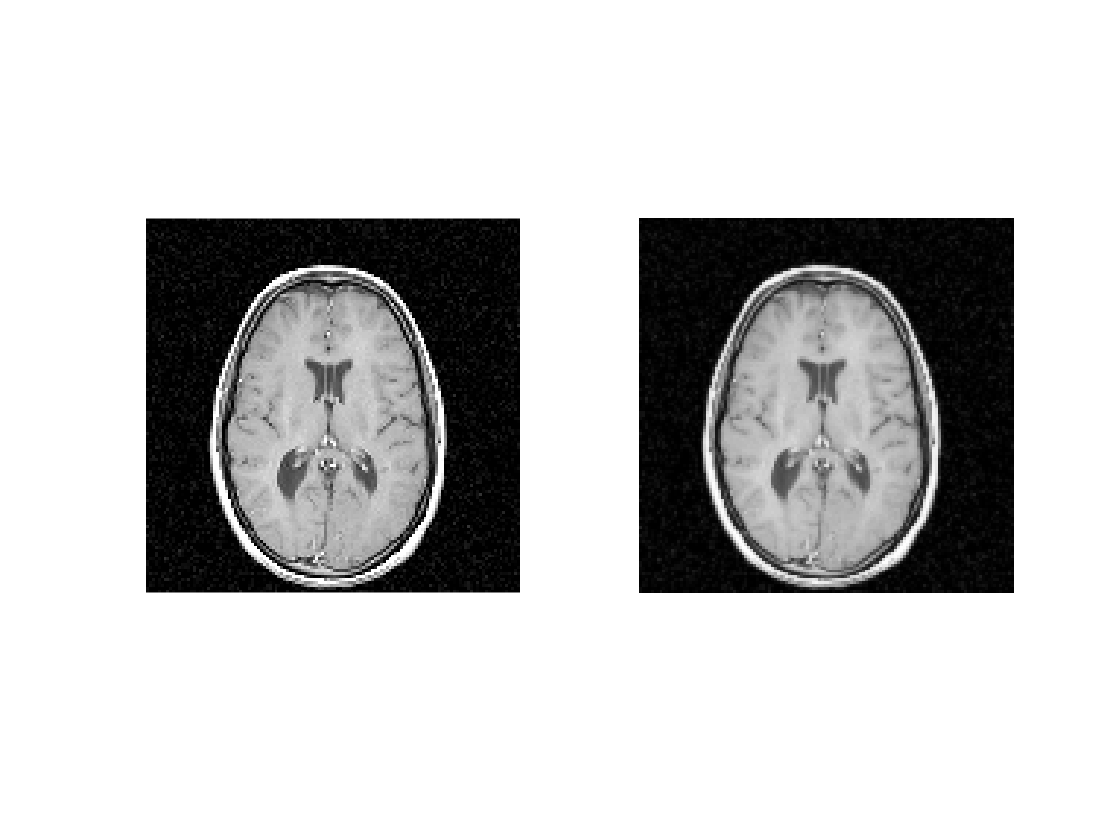

figure;
subplot(1,2,1), imshow(rescale(Im))
subplot(1,2,2), imshow(rescale(Im_G)) 

`imshow(I)` displays  grayscale image `I` in a figure. With image `I` of data type `single` or `double`, then values should be in the range [0, 1]. If pixel values are outside this range, then you can use the [`rescale`](https://localhost:31515/static/help/matlab/ref/rescale.html) function to scale pixel values to the range [0, 1]

Compare the original and filtered image profiles

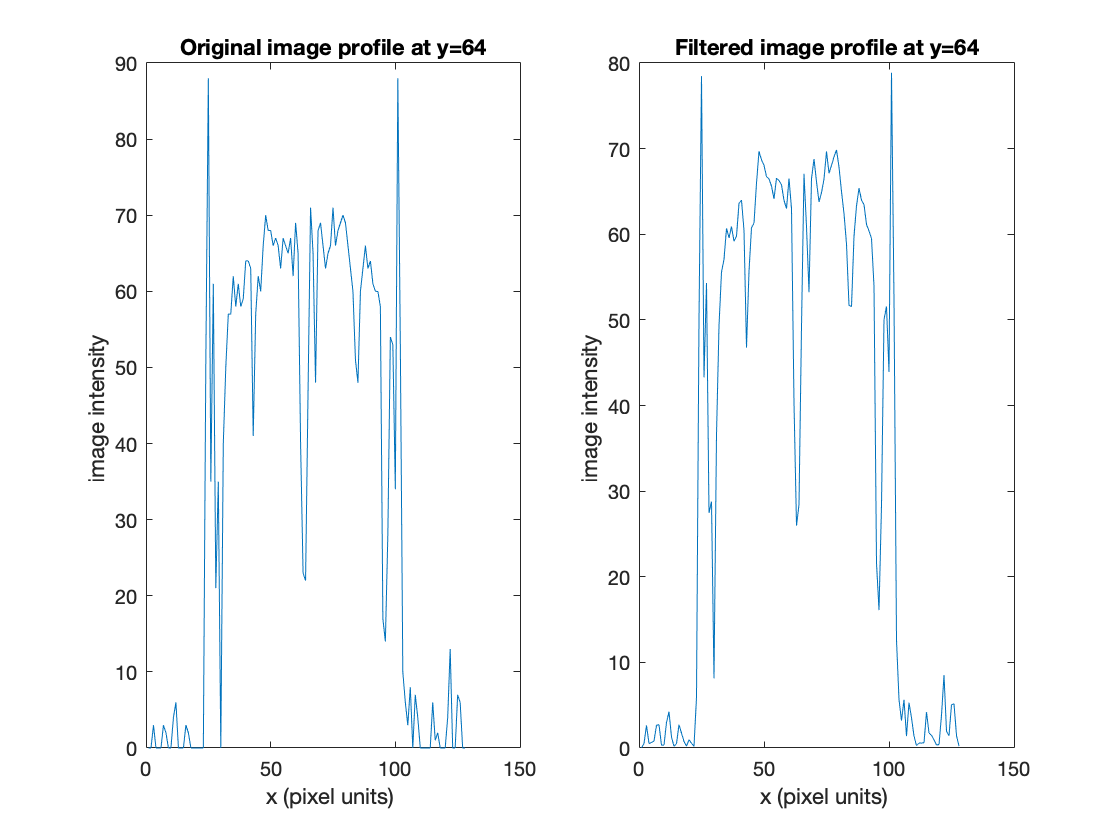

figure;
subplot(1,2,1) 
plot(Im(sl,:)), xlabel('x (pixel units) '), ylabel('image intensity ')
title(strcat('Original image profile at y= ',num2str(sl)));
subplot(1,2,2), imshow(Im_G) 
plot(Im_G(sl,:)), xlabel('x (pixel units) '), ylabel('image intensity ')
title(strcat('Filtered image profile at y= ',num2str(sl)));

to make the plot directly comparable put the same y axis range in both subplot using  ylim as follows

figure;
subplot(1,2,1) 
plot(Im(sl,:)), xlabel('x (pixel units) '), ylabel('image intensity ')
title(strcat('Original image profile at y= ',num2str(sl)));
yl=ylim   % returns the current limits as a two-element vector

yl =      0    90


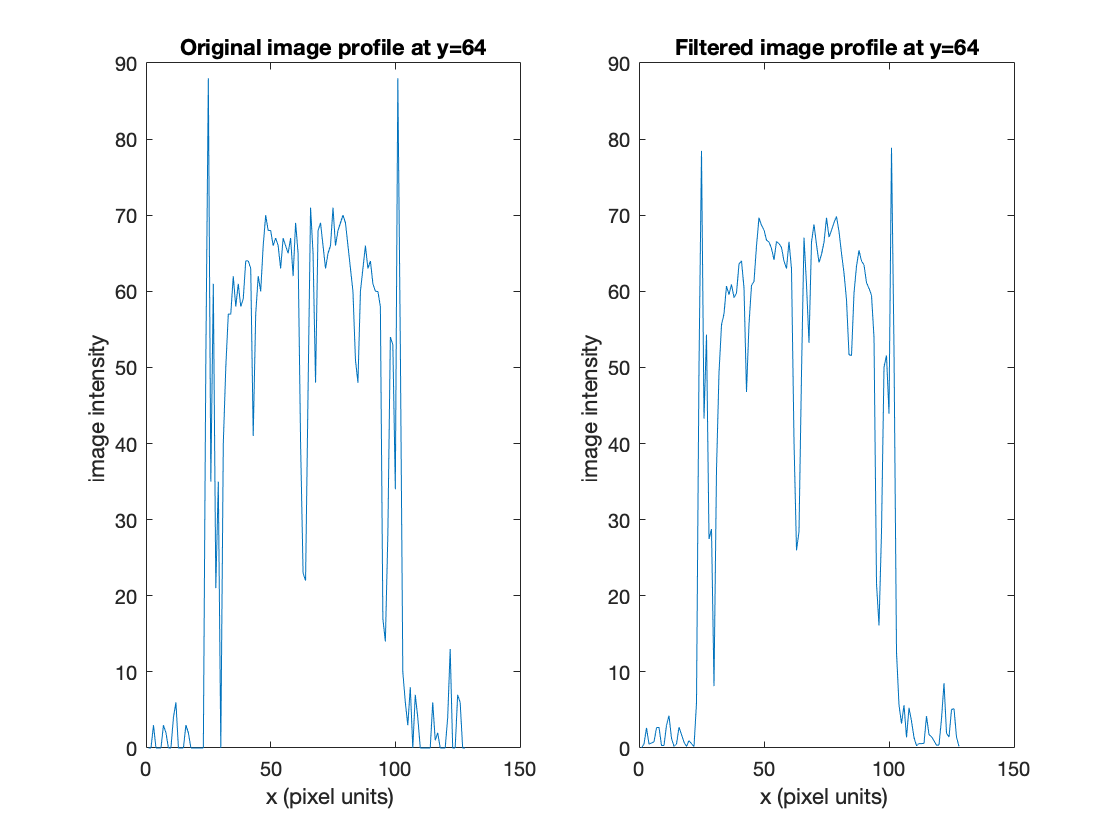

subplot(1,2,2), imshow(Im_G) 
plot(Im_G(sl,:)), xlabel('x (pixel units) '), ylabel('image intensity ')
ylim(yl)  % ylim(limits) sets the y-axis limits for the current axes or chart. 
% Specify limits as a two-element vector of the form [ymin ymax]. 
title(strcat('Filtered image profile at y= ',num2str(sl)));

Try with a larger sigma and compare the original and filtered image profiles

Im_G3 = imgaussfilt(Im,3); 

figure;
subplot(1,3,1) 
plot(Im(68,:)), xlabel('x (pixel units) '), ylabel('image intensity ')
yl=ylim 

yl =      0    90


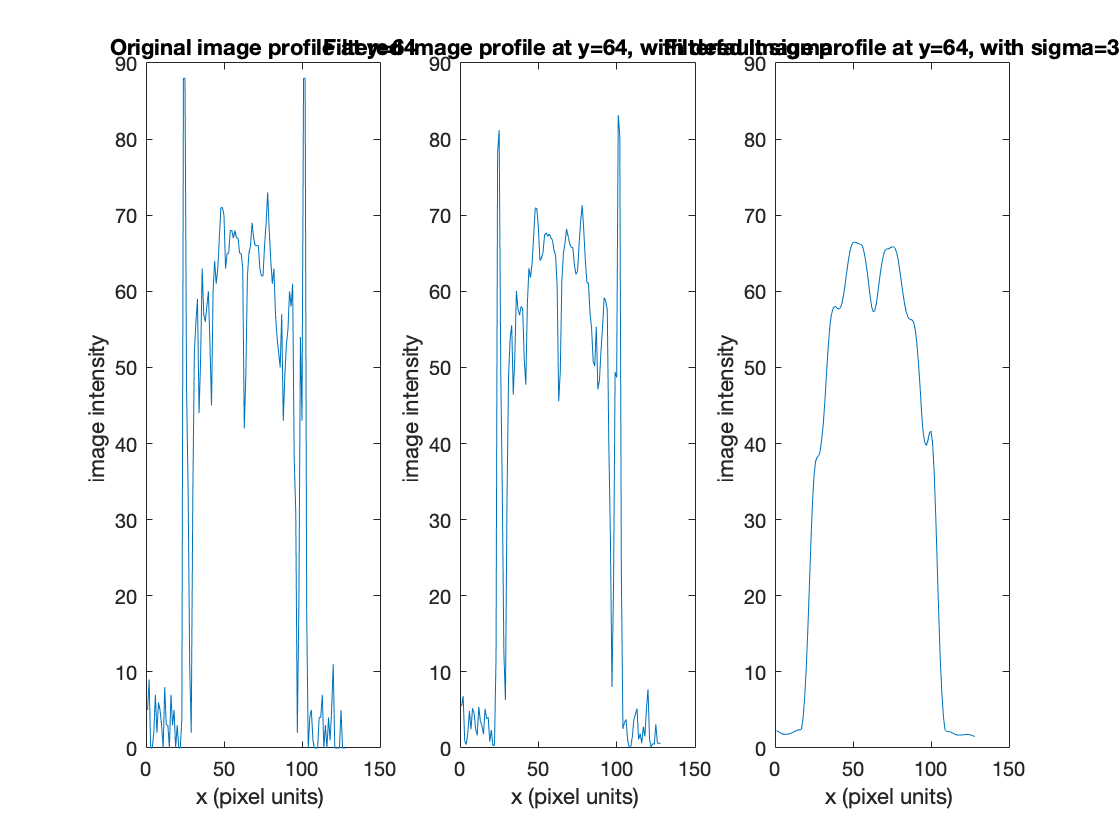

title(strcat('Original image profile at y= ',num2str(sl)));
subplot(1,3,2) 
plot(Im_G(68,:)), xlabel('x (pixel units) '), ylabel('image intensity ')
ylim(yl) 
title(strcat('Filtered image profile at y= ',num2str(sl), ', with default sigma'));
subplot(1,3,3)
plot(Im_G3(68,:)), xlabel('x (pixel units) '), ylabel('image intensity ')
ylim(yl) 
title(strcat('Filtered image profile at y= ',num2str(sl), ', with sigma=3'));

to make a direct comparison

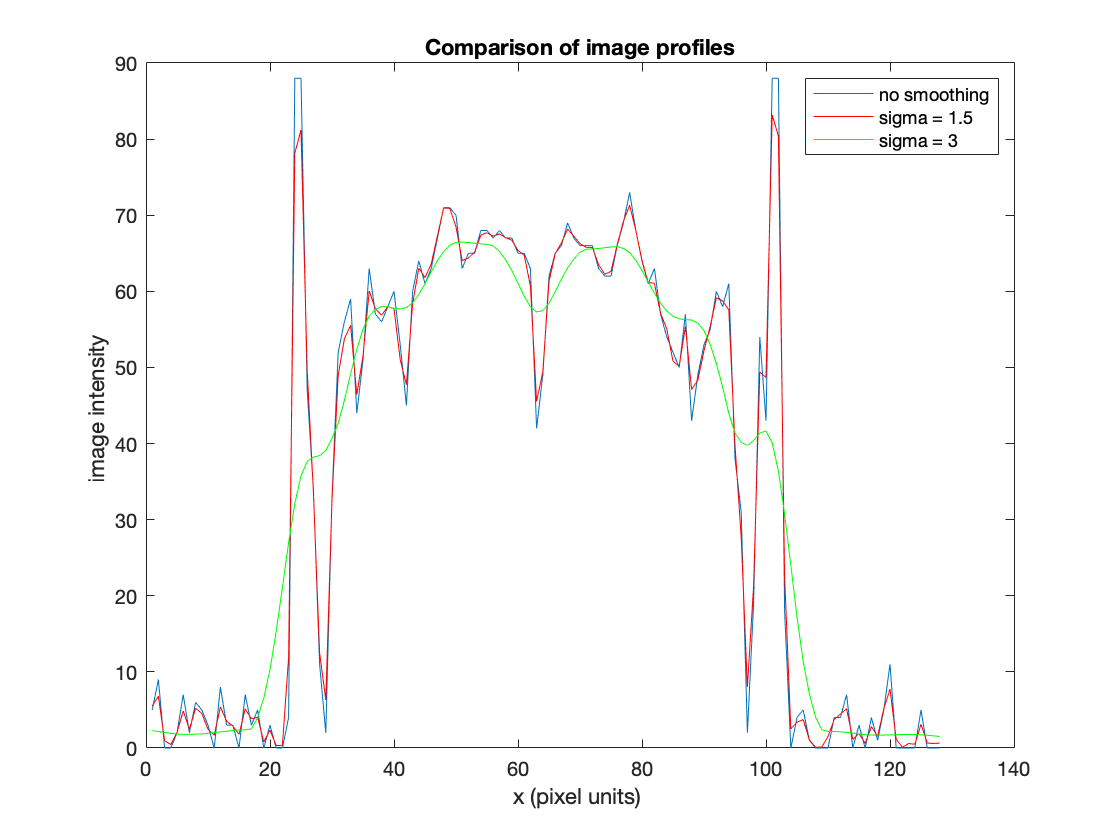

figure;
x=1:size(Im,1);
plot(x,Im(68,:),x,Im_G(68,:),'r',x,Im_G3(68,:),'g')
xlabel('x (pixel units) '), ylabel('image intensity ')
title(strcat('Comparison of image profiles'));
legend('no smoothing','sigma = 1.5 ','sigma = 3')

We reduced the noise (see the backgroud pixels), but the sharpness of edges is lost

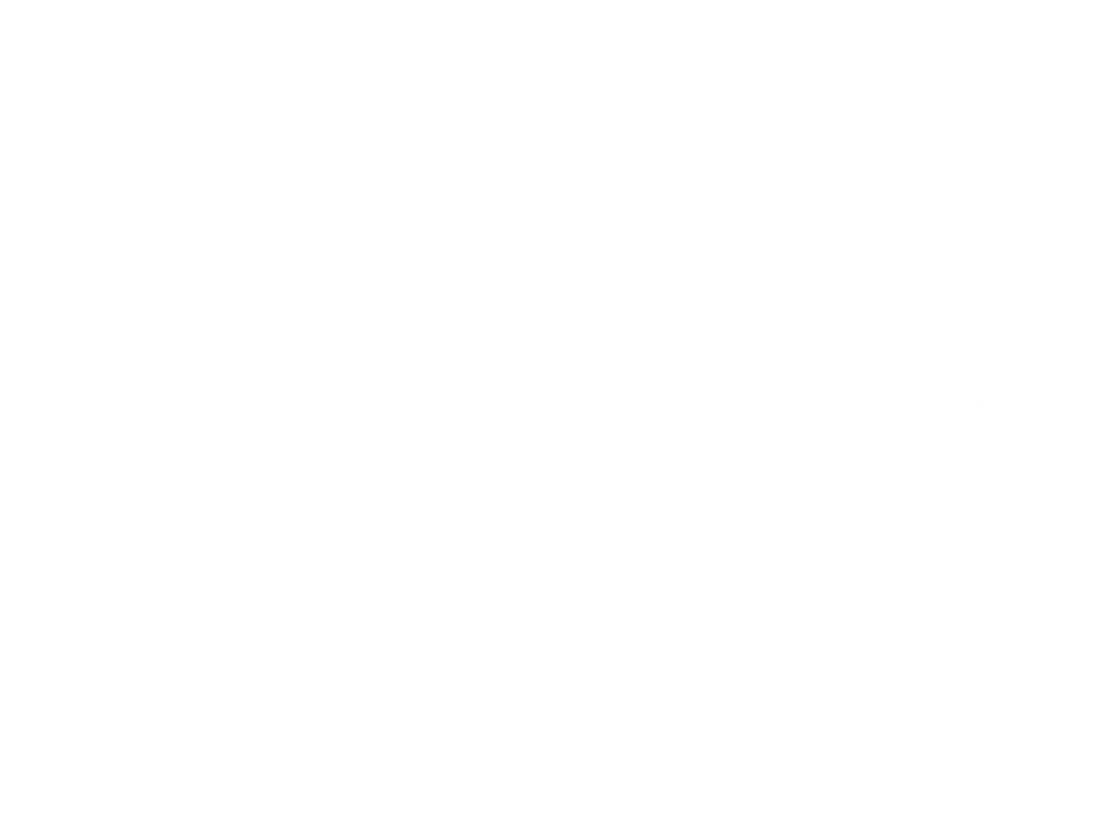

figure;
subplot(1,3,1), imshow(range(Im))
subplot(1,3,2), imshow(range(Im_G)) 
subplot(1,3,3), imshow(range(Im_G3)) 

You can try and compare the effect of other filters (see `medfilt2`, `wiener2,` `imfilter`, ...)

E.g. median filters are suitable to remove salt and pepper noise in the image (as in MRIslice_noise.png)